clc,clear,close all
c = 3e8;                         %光速 
Tr = 100e-6;                    %脉冲重复周期
totalR=c*Tr/2

totalR = 15000

f0 = 10e9;                      %载频
Tp = 10e-6;                      %脉冲宽度
B = 10e6;                         %带宽
u = B/Tp;                        %调频率
fs = 4*B;                        %采样率
N = 64;                          %脉冲数
t = 1/fs:1/fs:Tr;               %回波信号时间序列
SampleNumber=fix(fs*Tr)         %一个脉冲周期的采样点数；

SampleNumber = 4000

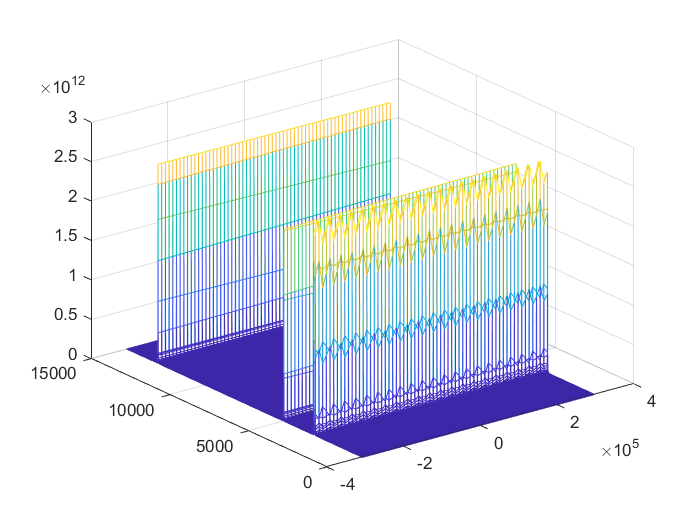

targetNumber=4;                            %目标个数
R0 = [3e3,3.1e3,5e3,13e3];                  %目标距离
v = [20,70,50,30];                           %径向速度
pnum = 4;                                  %保护单元
rnum = 10;                                 %参考单元
pfa = 1e-6;                                %恒虚警率
M_scale=1;                                %MTD的多普勒门
r_range=(0:length(t)-1)*totalR/(length(t)-1);
v_range = (-M_scale*N/2:M_scale*N/2-1)*c/2/f0/M_scale*N/Tr;
load("outtt.txt")
cfar=reshape(outtt,[4000,64]);
mesh(v_range,r_range,cfar)

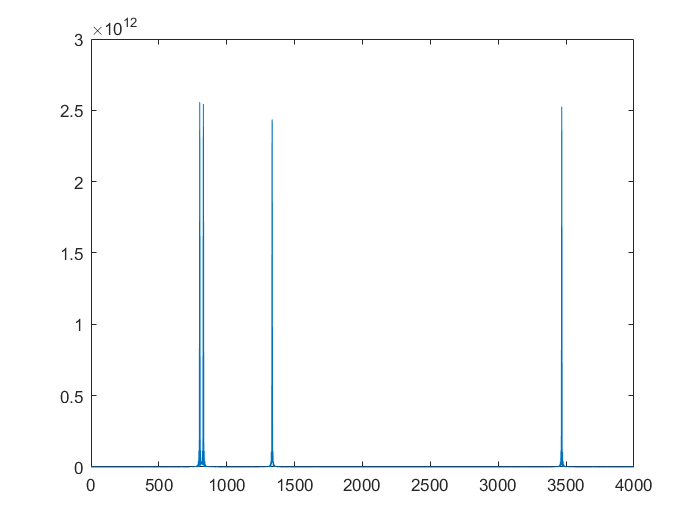

% plot(1:length(outtt(1,:)),outtt(6,:))
plot(1:4000,outtt(1:4000))